# Sample 5-4

## 周波数解析

画像スペクトル

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Fourier analysis

Spectrum of images

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

close all

### サンプル画像の準備

(Preparation of sample image)

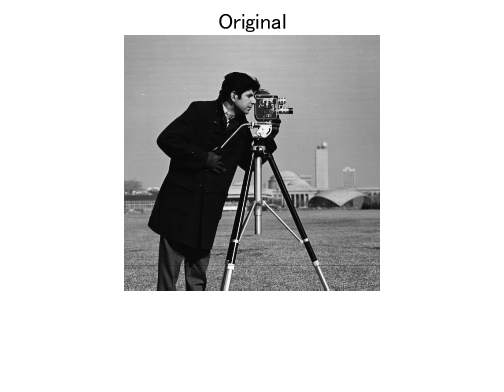

% Reading original image
u = im2double(imread('cameraman.tif'));
figure(1)
imshow(u)
title('Original')

### 画像（2変量信号） $\{u[\mathbf{n}]\in\mathbb{R}\}_{\mathbf{n}\in\mathbb{Z}^2}
$ のスペクトル

(Spectrum of an image (bivariate signal)  $\{u[\mathbf{n}]\in\mathbb{R}\}_{\mathbf{n}\in\mathbb{Z}^2}
$)

        
$$U\left(e^{\j\mathbf{\omega}^T}\right)= \sum_{\mathbf{n}\in\Omega\subset\mathbb{Z}^2}u[\mathbf{n}]e^{-\j\mathbf{\omega}^T \mathbf{n}},\ \mathbf{\omega}\in\mathbb{R}^2$$


ただし， $\Omega$は画像のサポート領域を意味する． (where  $\Omega$ denotes the support region of the image.)

DFT(FFT)によるDSFTの周波数サンプル計算 (Frequency sampling of DSFT by DFT (FFT))

        
$$U[\mathbf{k}] = \left.U\left(e^{j\mathbf{\omega}^T}\right)\right|_{\mathbf{\omega}=2\pi \mathbf{Q}^{-T}\mathbf{k}},\ \mathbf{k}\in\mathcal{N}\left(\mathbf{Q}^T\right)$$


以下では周期行列 $\mathbf{Q}$ を対角行列 (In the following, the periodic matrix  $\mathbf{Q}$ is set to a diagonal matrix)

         
$$\mathbf{Q}=\left(\begin{array}{cc}
N_1 & 0 \\
0 & N_2 \end{array}\right)$$
 

に設定する．すなわち，(That is,)

        
$$\mathcal{N}(\mathbf{Q})=\mathcal{N}(\mathbf{Q}^T)=\{0,1,2,\cdots,N_1-1\}\times\{0,1,2,\cdots,N_2-1\}$$


        
$$N=\left|\mathcal{N}(\mathbf{Q})\right|=\left|\det(\mathbf{Q})\right|=N_1N_2$$


ただし，$\mathcal{N}(\cdot)$は基本周期内の整数ベクトル集合　(where $\mathcal{N}(\cdot)$ denotes a set of interger vectors in the fundamental pallalelpiped as) 

        
$$\mathcal{N}(\mathbf{P})\colon=\{\mathbf{Px}\in\mathbb{Z}^D|\ \mathbf{x}\in[0,1)^D\}$$


であり，$\Omega\subseteq\mathcal{N}(\mathbf{Q})$ を仮定する．( and $\Omega\subseteq\mathcal{N}(\mathbf{Q})$ is assumed.)

% Setting the number of frequency sample points in [0,2π)
nPoints1 = 256; % N_1
nPoints2 = 256; % N_2

% Spectrum of u[n]
U = fft2(u,nPoints1,nPoints2);

### 表示のための係数シフト

(Coefficient shift for display)

直流(DC)成分を配列の中心にシフト (Shift the direct current (DC) component to the center of the array)

% Shift the DC Coef. to the center
Usft = fftshift(U);

% Frequency sampling points
[w2,w1] = meshgrid(-pi:2*pi/nPoints2:pi-2*pi/nPoints2,-pi:2*pi/nPoints1:pi-2*pi/nPoints1);

### 振幅スペクトル $\left|U\left(e^{\j\mathbf{\omega}^T}\right)\right|$の表示

Display of magnitude spectrum $\left|U\left(e^{\j\mathbf{\omega}^T}\right)\right|$

        
$$\left|U\left(e^{\j\mathbf{\omega}^T}\right)\right|=\sqrt{\Re\left(U\left(e^{\j\mathbf{\omega}^T}\right)\right)^2+\Im\left(U\left(e^{\j\mathbf{\omega}^T}\right)\right)^2}$$


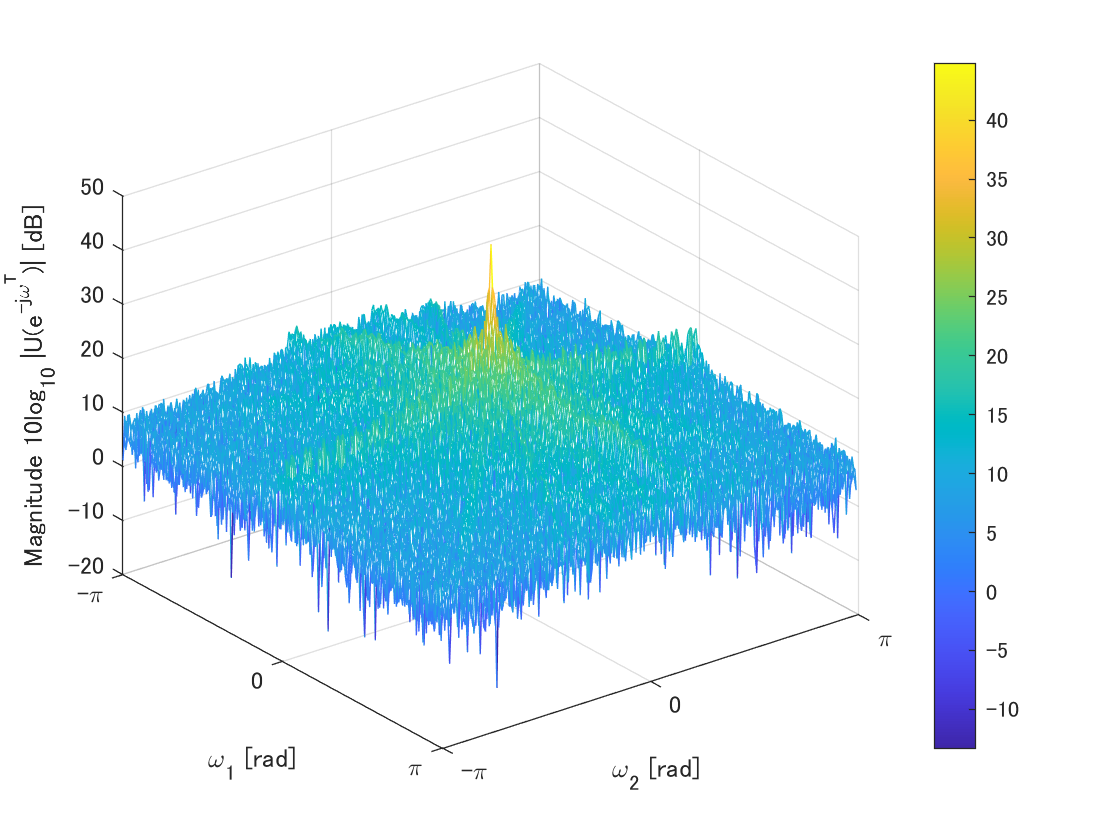

% Calculation of the magnitude spectrum
Umag = abs(Usft);

% Display the magnitude spectrum
figure(2)
mesh(w1,w2,10*log10(Umag))
ax = gca;
xlabel('\omega_2 [rad]')
ylabel('\omega_1 [rad]')
zlabel('Magnitude 10log_{10} |U(e^{-j\omega^T})| [dB]')
axis ij
ax.XLim = [-pi pi];
ax.XTick = [ -pi 0 pi ];
ax.XTickLabel = { '-\pi', '0', '\pi'};
ax.YLim = [-pi pi];
ax.YTick = [ -pi 0 pi ];
ax.YTickLabel = { '-\pi', '0', '\pi'};
colorbar(ax)

### 位相スペクトル $\angle U\left(e^{\j\mathbf{\omega}^T}\right)$の表示

(Display of phase spectrum $\angle U\left(e^{\j\mathbf{\omega}^T}\right)$)

        
$$\angle U\left(e^{\j\mathbf{\omega}^T}\right)=\tan^{-1}\frac{\Im\left(U\left(e^{\j\mathbf{\omega}^T}\right)\right)}{\Re\left(U\left(e^{\j\mathbf{\omega}^T}\right)\right)}$$


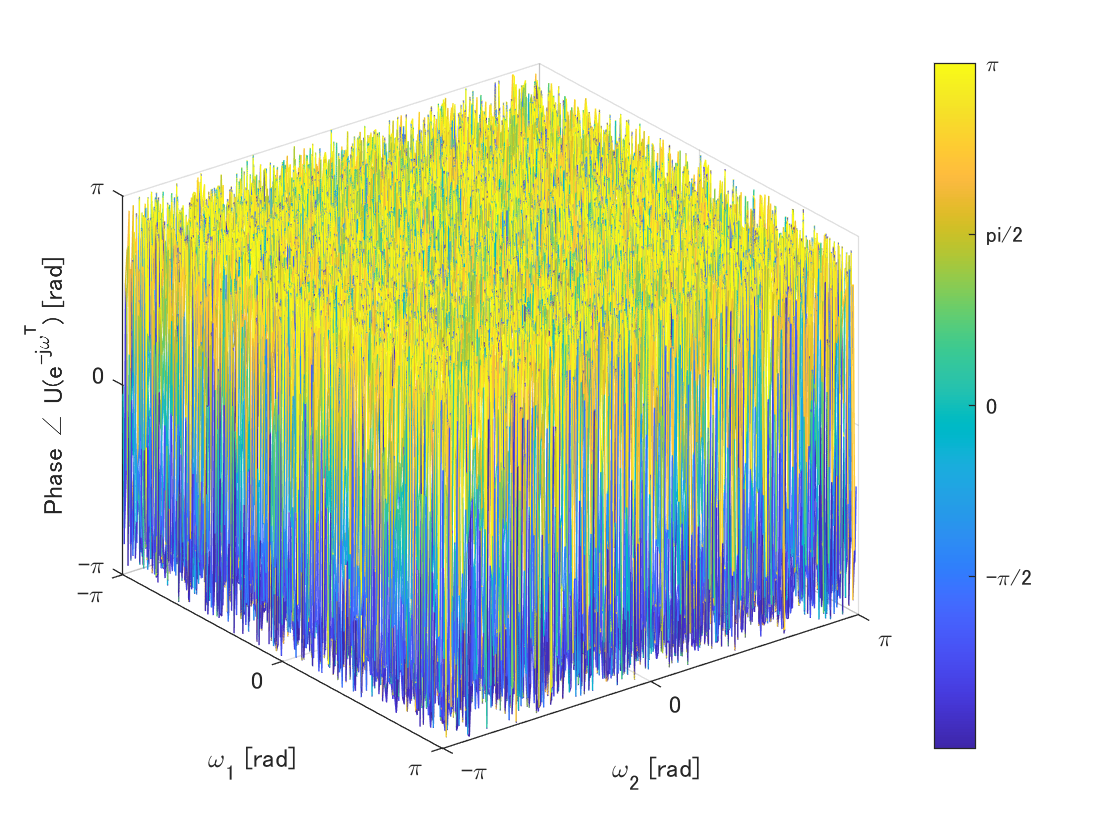

% Calculation of the magnitude spectrum
Uphs = angle(Usft);

% Display the magnitude spectrum
figure(3)
mesh(w1,w2,Uphs)
ax = gca;
xlabel('\omega_2 [rad]')
ylabel('\omega_1 [rad]')
zlabel('Phase \angle U(e^{-j\omega^T}) [rad]')
axis ij
ax.XLim = [-pi pi];
ax.XTick = [ -pi 0 pi ];
ax.XTickLabel = { '-\pi', '0', '\pi'};
ax.YLim = [-pi pi];
ax.YTick = [ -pi 0 pi ];
ax.YTickLabel = { '-\pi', '0', '\pi'};
ax.ZLim = [-pi pi];
ax.ZTick = [ -pi 0 pi ];
ax.ZTickLabel = { '-\pi', '0', '\pi'};
colorbar(ax,'Ticks',[ -pi -pi/2 0 pi/2 pi],'TickLabels', { '-\pi', '-\pi/2', '0', 'pi/2', '\pi'})

### スペクトル$U\left(e^{\j\mathbf{\omega}^T}\right)$からの画像再構成 

(Reconstruction from the spectrum $U\left(e^{\j\mathbf{\omega}^T}\right)$)

       
$$u[\mathbf{n}]=\frac{1}{(2\pi)^2}\int_{\mathbf{\omega}\in[0,2\pi)^2}U\left(e^{\j\mathbf{\omega}^T}\right)d\mathbf{\omega},\ \mathbf{n}\in\Omega\subset\mathbb{Z}^2 $$


IDFT(IFFT)による再構成 (Reconstruction by IDFT (IFFT))

        
$$u[\mathbf{n}] = \frac{1}{\left|\det(\mathbf{Q})\right|}\sum_{\mathbf{n}\in\mathcal{N}(\mathbf{Q})}U[\mathbf{k}]e^{-\j2\pi\mathbf{k}\mathbf{Q}^{-1}\mathbf{n}},\ \mathbf{n}\in\Omega\subseteq\mathcal{N}(\mathbf{Q}) $$


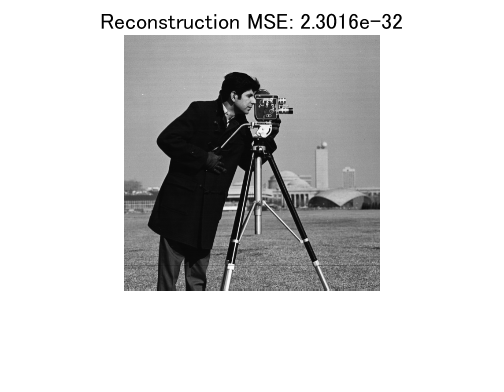

% Reconstruction from the spectrum
r = ifft2(U,nPoints1,nPoints2);

% Clipping to the support region Ω
urec = r(1:size(u,1),1:size(u,2)); 
figure(4)
imshow(urec)
% MSE
mymse = @(x,y) mean((double(x)-double(y)).^2,'all');
title(['Reconstruction MSE: ' num2str(mymse(u,urec))])

### 振幅スペクトル$\left|U\left(e^{\j\mathbf{\omega}^T}\right)\right|$からの画像再構成 

(Reconstruction from the spectrum$\left|U\left(e^{\j\mathbf{\omega}^T}\right)\right|$)

       
$$u_\mathrm{mag}[\mathbf{n}]=\frac{1}{(2\pi)^2}\int_{\mathbf{\omega}\in[0,2\pi)^2}\left|U\left(e^{\j\mathbf{\omega}^T}\right)\right|d\mathbf{\omega},\ \mathbf{n}\in\Omega\subset\mathbb{Z}^2 $$


IDFT(IFFT)による計算 (Calculation by IDFT (IFFT))

        
$$u_\mathrm{mag}[\mathbf{n}] = \frac{1}{\left|\det(\mathbf{Q})\right|}\sum_{\mathbf{n}\in\mathcal{N}(\mathbf{Q})}\left|U[\mathbf{k}]\right|e^{-\j2\pi\mathbf{k}\mathbf{Q}^{-1}\mathbf{n}},\ \mathbf{n}\in\Omega\subseteq\mathcal{N}(\mathbf{Q}) $$


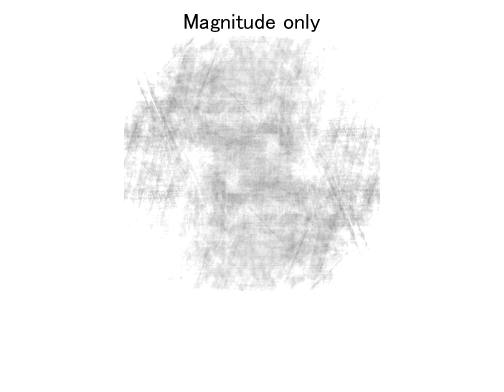

% Reconstruction from the spectrum
rmag = ifft2(ifftshift(Umag),nPoints1,nPoints2);

% Clipping to the support region Ω
umag = rmag(1:size(u,1),1:size(u,2)); 
figure(5)
imshow(umag+.5)
title('Magnitude only')

### 位相スペクトル$\angle U\left(e^{\j\mathbf{\omega}^T}\right)$からの画像再構成 

(Reconstruction from the spectrum $\angle U\left(e^{\j\mathbf{\omega}^T}\right)$)

       
$$u_\mathrm{phs}[\mathbf{n}]=\frac{1}{(2\pi)^2}\int_{\mathbf{\omega}\in[0,2\pi)^2}e^{\j\angle U\left(e^{\j\mathbf{\omega}^T}\right)}e^{-\j\mathbf{\omega}^T\mathbf{n}}d\mathbf{\omega},\ \mathbf{n}\in\Omega\subset\mathbb{Z}^2 $$


IDFT(IFFT)による計算 (Calculation by IDFT (IFFT))

        
$$u_\mathrm{phs}[\mathbf{n}] = \frac{1}{\left|\det(\mathbf{Q})\right|}\sum_{\mathbf{n}\in\mathcal{N}(\mathbf{Q})}e^{\j\angle U[\mathbf{k}]}e^{-\j2\pi\mathbf{k}\mathbf{Q}^{-1}\mathbf{n}},\ \mathbf{n}\in\Omega\subseteq\mathcal{N}(\mathbf{Q}) $$


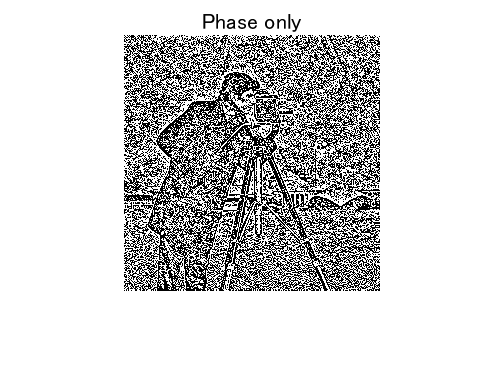

% Reconstruction from the spectrum
rphs = ifft2(exp(1j*ifftshift(Uphs)),nPoints1,nPoints2);

% Clipping to the suppor region Ω
uphs = rphs(1:size(u,1),1:size(u,2)); 
figure(6)
imshow(nPoints1*nPoints2*real(uphs)+.5)
title('Phase only')

© Copyright, Shogo MURAMATSU, All rights reserved.